#### **Manoli Philip Tramountanas**

#### **AMATH 301 A - Autumn 2020**

#### **October 16, 2020**

# **Homework 2 Solutions**

## **Problem 1**

a) Given $g\left(x\right)=f\left(x\right)-2\pi =x^5 -2x^4 +4x^3 -2x^2 +x-1-\mathrm{cos}\left(30x\right)-2\pi$, find $x$ for which $g\left(x\right)=0$.

b) Finding the exact solution to part 'a':

f1 = @(x) (x^5) - (2*x^4) + (4*x^3) - (2*x^2) + x - 1 - cos(30*x);
g = @(x) f1(x) - 2*pi;

sol = fzero(g, 1.5);
disp("Exact solution found by using the built-in root finder: "...
    + sol);

Exact solution found by using the built-in root finder: 1.4964


c) Finding the root in the interval $\left\lbrack -10,10\right\rbrack$ with a tolerance of ${10}^{-9}$ using the bisection method:

left = -10;
right = 10;
mid(1) = (left + right)/2;
tol = 1e-9;
itrBi = 1;

while (abs(g(mid(itrBi))) > tol)
    if (g(mid(itrBi)) * g(left) < 0)
        right = mid(itrBi);
    elseif (g(mid(itrBi)) * g(right) < 0)
        left = mid(itrBi);
    else
        return;
    end
    
    mid(itrBi + 1) = (left + right)/2;
    itrBi = itrBi + 1;
end

errBisection = abs(sol - mid);
disp("Solution found by using the bisection method: " ...
    + mid(end));

Solution found by using the bisection method: 1.4964


d) Find the root using Newton's method with an initial guess of $x_0 =10$ and a tolerance of ${10}^{-9}$.

dg = @(x) (5*x^4) - (8*x^3) + (12*x^2) - (4*x) + 1 + 30*sin(30*x);
x1(1) = 10;
itrNewton = 1;

while(abs(g(x1(itrNewton))) > tol)
    x1(itrNewton + 1) = x1(itrNewton) - (g(x1(itrNewton))/dg(x1(itrNewton)));
    itrNewton = itrNewton + 1;
end

errNewton = abs(sol - x1);
disp("Solution found by using Newton's method: " ...
    + x1(end));

Solution found by using Newton's method: 1.4964


e-j) Plotting the error vectors from parts 'c' and 'd'.

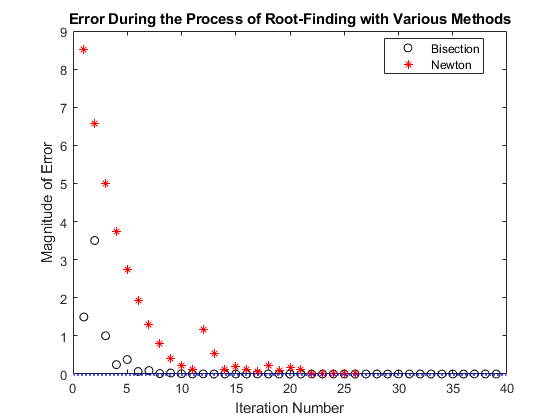

set(gca, 'Fontsize', 15);

figure(1);
plot(1:itrBi, errBisection, 'ko', ...
    1:itrNewton, errNewton, 'r*', ...
    'Linewidth', 0.5);
hold on
yline(1e-9, 'b:', 'Linewidth', 2);

title('Error During the Process of Root-Finding with Various Methods');
xlabel('Iteration Number');
ylabel('Magnitude of Error');
legend('Bisection', 'Newton', 'Location', 'Best');

## Problem 2

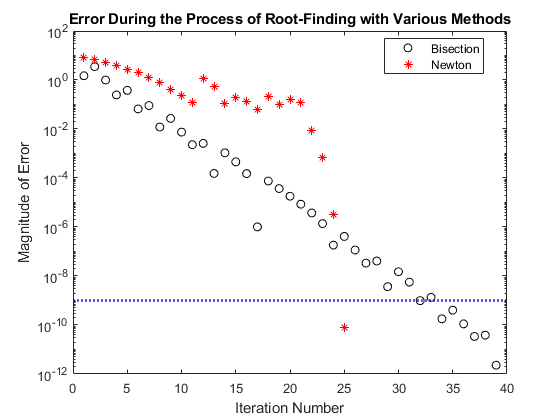

figure(2);
semilogy(1:itrBi, errBisection, 'ko', ...
    1:itrNewton, errNewton, 'r*', ...
    'Linewidth', 0.5);
hold on
yline(1e-9, 'b:', 'Linewidth', 2);

title('Error During the Process of Root-Finding with Various Methods');
xlabel('Iteration Number');
ylabel('Magnitude of Error');
legend('Bisection', 'Newton', 'Location', 'Best');

Newton's method seems to have performed better than the bisection method. This is because it took less iterations for Newton's method to find the root within the tolerance, and the calculations for Newton's method stopped immediately after a value was found within the tolerance (whereas the calculations for the bisection method did not).

## Problem 3

For this problem, let $f\left(x\right)$ be defined by $f\left(x\right)=x*\sin \left(x\right)$ with a known root at $x=0$.

a) Finding the root and error (using exact solution $x=0$) using Newton's method with the following restrictions/inputs: initial guess of $x_0 =1\ldotp 8$, maximum of 50 steps, tolerance of ${10}^{-10}$.

f2 = @(x) x.*sin(x);
df2 = @(x) sin(x) + x*cos(x);
tol = 1e-10;
x2(1) = 1.8;
itr2 = 1;

for k = 1:50
    if (abs(f2(x2(k))) < tol)
        break;
    end
    x2(k + 1) = x2(k) - (f2(x2(k))/df2(x2(k)));
    itr2 = itr2 + 1;
end

disp("Error for x0 = 1.8: " + abs(x2(end)));

Error for x0 = 1.8: 5.0971e-06


b) Finding the root and error (using exact solution $x=0$) using Newton's method with the following restrictions/inputs: initial guess of $x_0 =1\ldotp 9$, maximum of 50 steps, tolerance of ${10}^{-10}$.

x3(1) = 1.9;
itr3 = 1;

for k = 1:50
    if (abs(f2(x3(k))) < tol)
        break;
    end
    x3(k + 1) = x3(k) - (f2(x3(k))/df2(x3(k)));
    itr3 = itr3 + 1;
end

disp("Error for x0 = 1.9: " + abs(x3(end)));

Error for x0 = 1.9: 3.1416


c) Plot of $f\left(x\right)$ with tangent lines for $x=1\ldotp 8$ and $x=1\ldotp 9$:

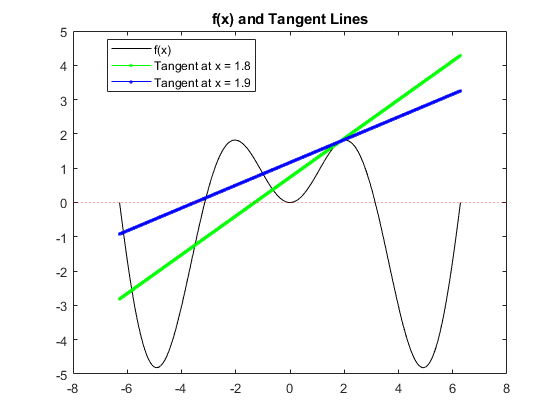

x4 = linspace(-2*pi, 2*pi, 1000);
tanLine = @(x,x0) df2(x0)*(x-x0) + f2(x0);
figure(3);
plot(x4, f2(x4), 'k-', ...
    x4, tanLine(x4, 1.8), 'g.-', ...
    x4, tanLine(x4, 1.9), 'b.-'),
hold on
yline(0, 'r:');
title('f(x) and Tangent Lines');
legend('f(x)', ...
    'Tangent at x = 1.8', ...
    'Tangent at x = 1.9', ...
    'Location', 'Best');

The errors obtained for parts 'a' and 'b' are not the same. This is because as seen on the graph of $f\left(x\right)$ and relevant tangent lines, there is a maximum of $f\left(x\right)$ very close to $x=1\ldotp 8$ and $x=1\ldotp 9$, meaning that $\frac{d}{\textrm{d}x}f\left(x\right)$ was very close to 0. Because the formula for Newton's method calculations involves adding a term including division by $\frac{d}{\mathrm{d}x}f\left(x\right)$ at $x_0$ (in this case a very large term), the initial guesses produced entirely different second guesses. In this case, the second guess produced by $x_0 =1\ldotp 9$ was to the left of the root at $x=-\pi$ as pictured by the root of the appropriate tangent line on the aforementioned graph. This caused the Newton's method calculation for that initial guess to find the root at $x=-\pi$, and because $|0-\pi |=\pi$, the calculated error was roughly equal to $\pi$ despite a root of the function being found.